clear; close all; clc

# Code to use Maximal Overlap Discrete Wavelet Transform (MODWT) to Analyze EMG Data

**Code based on:** Shawhin Talebi's code

**Modified by:** Diego A. Rueda

`Universidad Industrial de Santander`

`Load Data`

subject = 1;
taskname = 'ABDSLOW1';

% load the kinematics data
Filename = ['S' int2str(subject) '_' taskname];
KinFileName = ['../Kinematics/RoM/' Filename '.mat'];
load(['../Kinematics/RoM/' Filename '.mat']);

% load the EMG data
load(['../EMG/RoM/' Filename '_emg.mat']);

% synchronise EMG and Kinematics data

sync = EMG_raw(:,17);
selection = find(sync == 257);
EMG_new = EMG_raw(selection,1:14);
EMG_filtered = ExampleEMG_Filter(EMG_new, samplefreq);
EMG = EMG_new(:,2);

Perform Wavelet Transform

% Define number of levels to use
numLevels = 8;

% perform maximal overlap discrete wavelet transform
wt = modwt(EMG, 'sym4', numLevels);

Compare Coeffitiens for all MODWT Scales

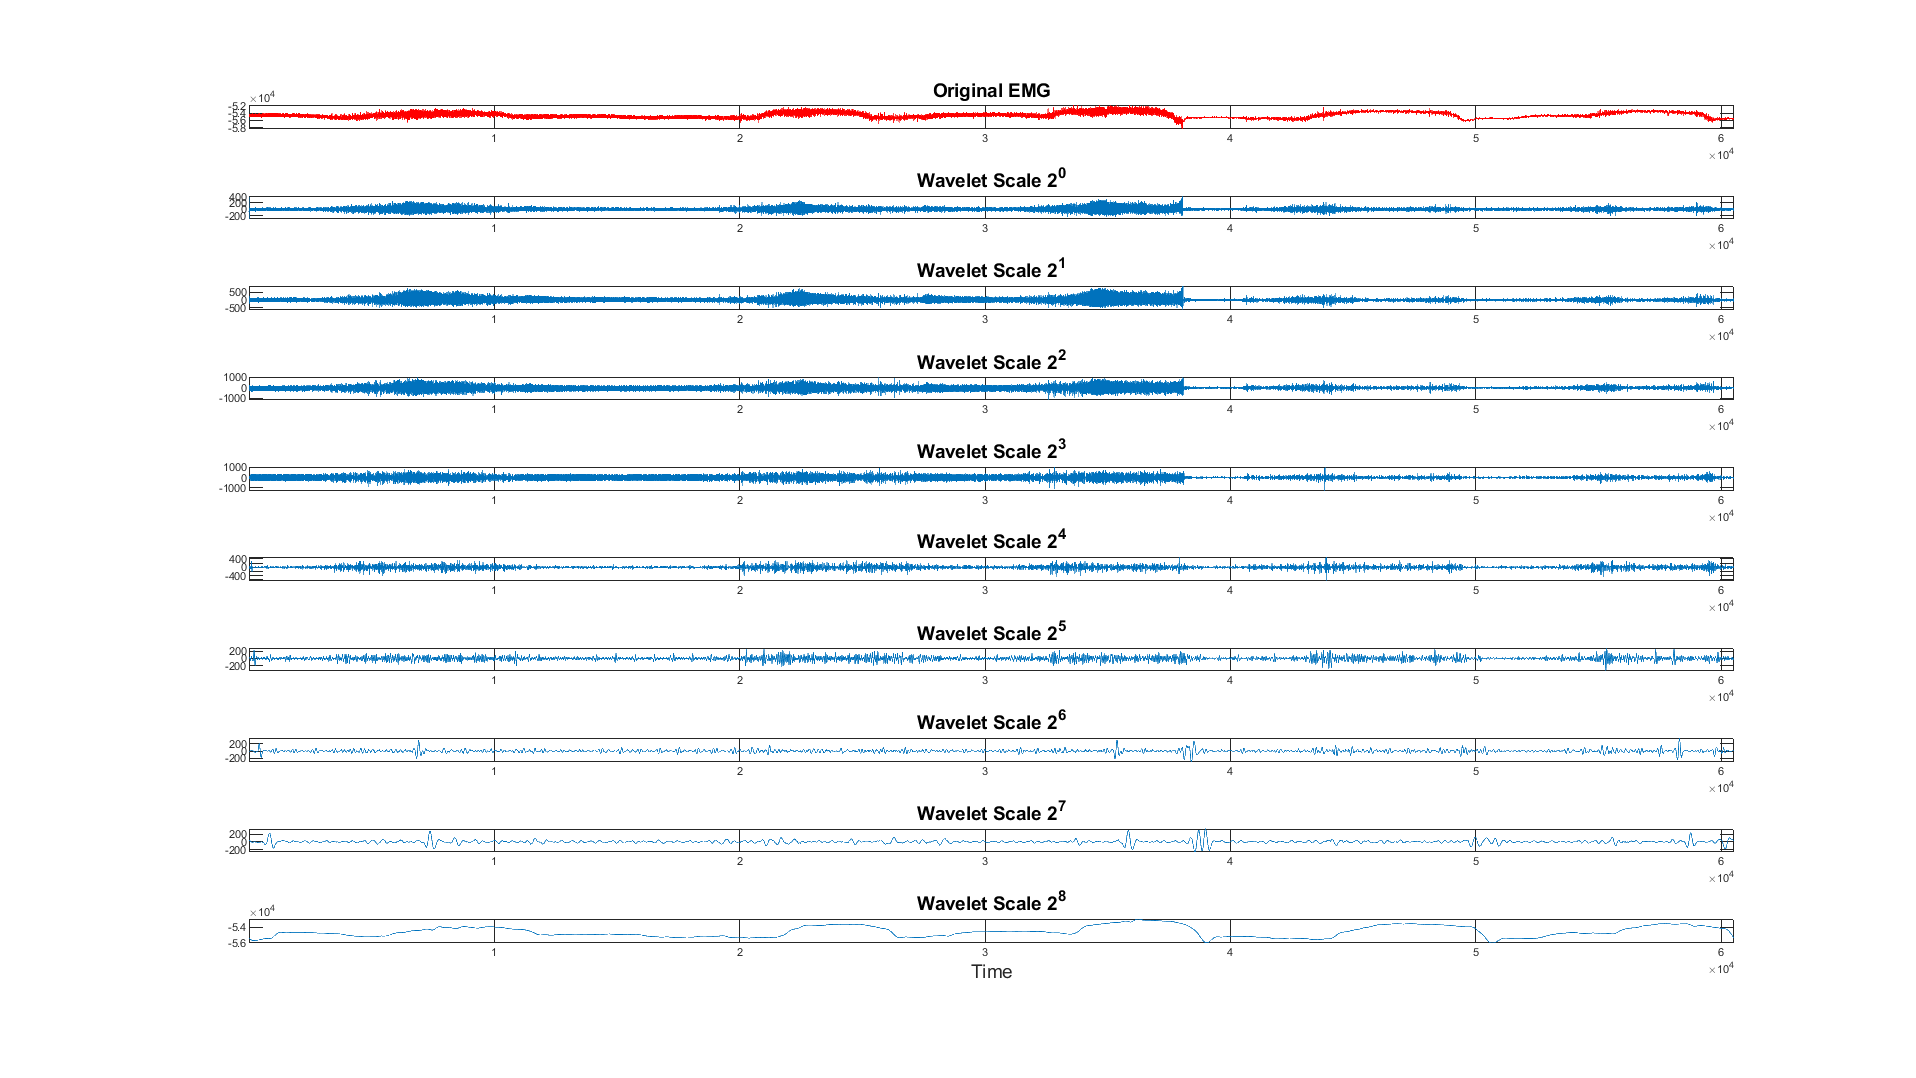

% get number of Wavelet Scales

[numScales, ~] = size(wt);

% create figure
fig = figure(1);
fig.Units = 'normalized';
fig.Position = [0 0 1 1];

% plot original signal
subplot(numScales+1,1,1)
plot(EMG, 'r-')
title('Original EMG', 'FontSize', 14)
axis tight

% plot wavelet scale coeffitients
for i=2:numScales+1
    subplot(numScales+1,1,i)
    plot(wt(i-1,:))
    title(strcat('Wavelet Scale 2^', string(i-2)), 'FontSize', 14)
    axis tight
end

xlabel('Time', 'FontSize', 14)

print('waveletTransform_signal_decomposition', '-dpng');

Reconstruct Signal via Inverse MODWT

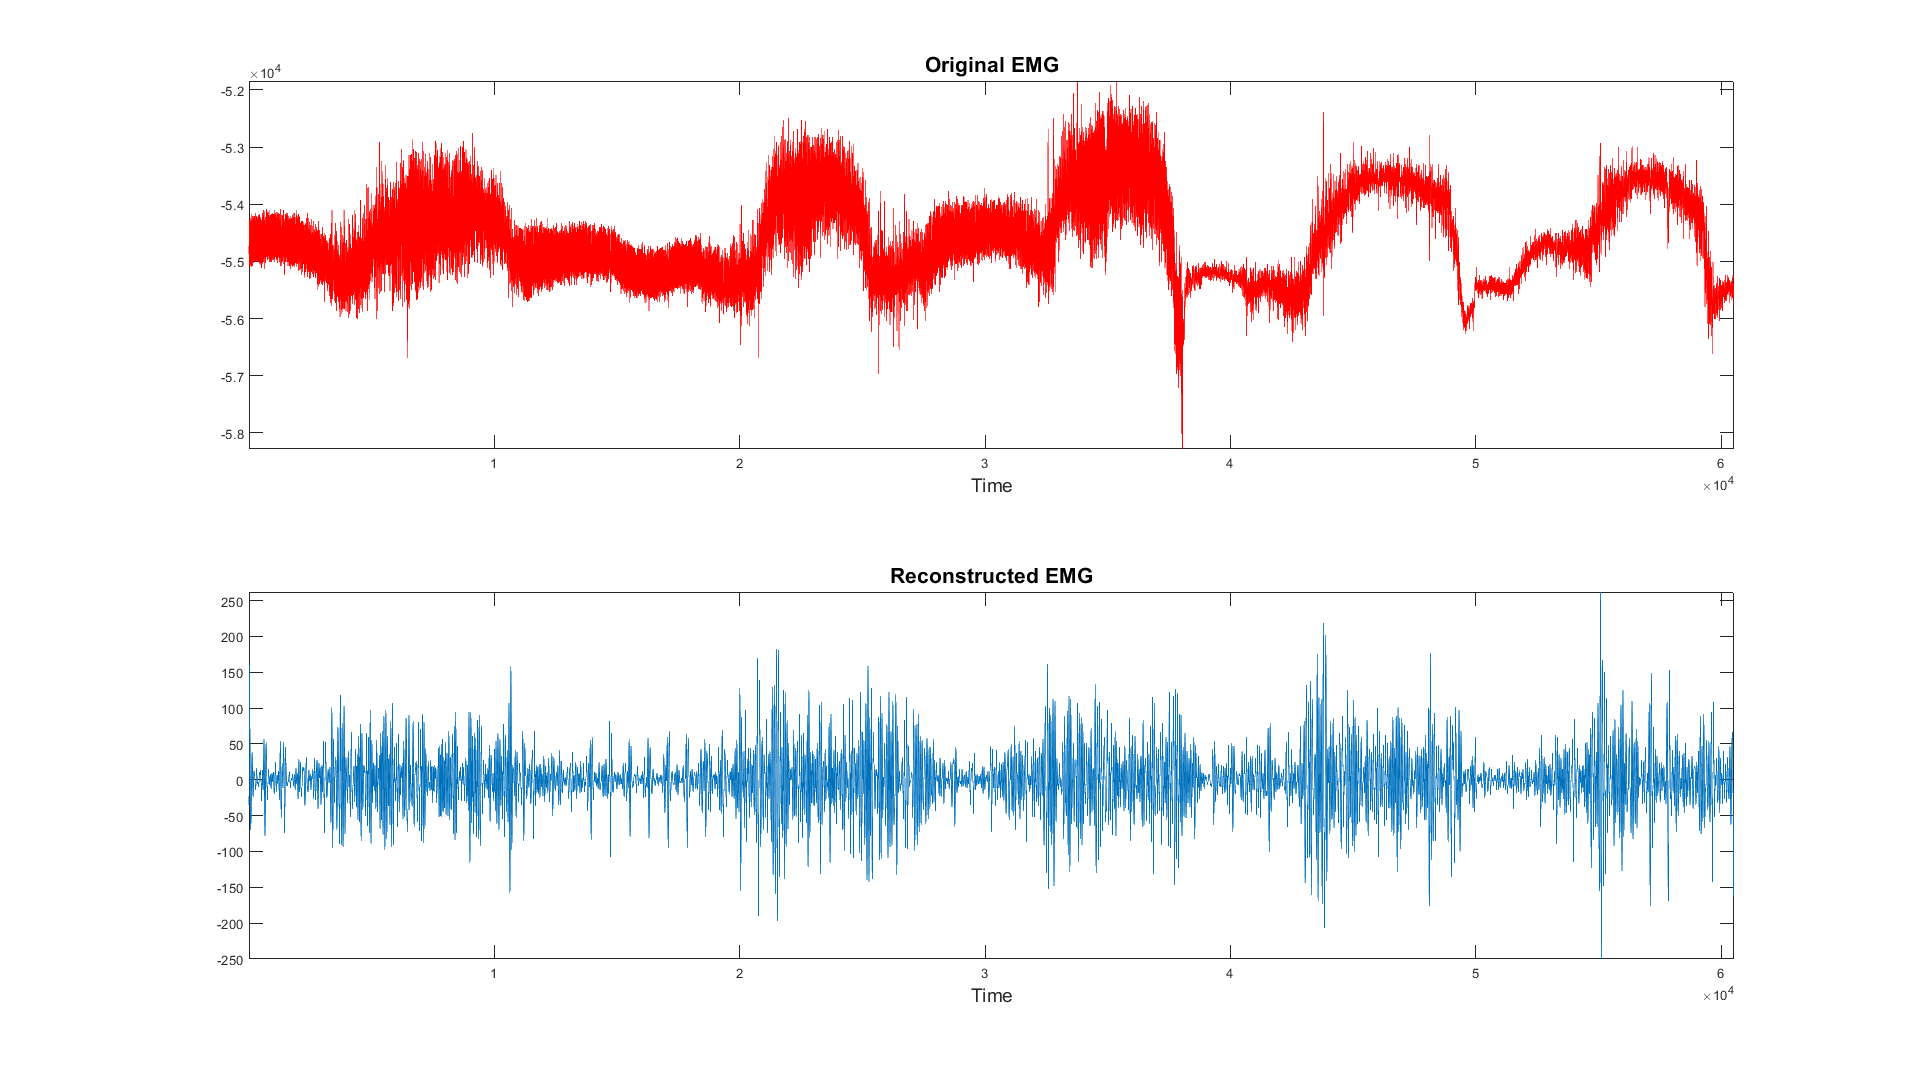

% create figure
fig = figure(2);
fig.Units = 'normalized';
fig.Position = [0 0 1 1];

recwt = zeros(size(wt));

recwt(6,:) = wt(6,:);
recEMG = imodwt(recwt, 'sym4');
% compare original signal and reconstructed
% plot original signal

subplot(2,1,1)
plot(EMG, 'r-')
title('Original EMG', 'FontSize', 16)
xlabel('Time', 'FontSize', 14)
axis tight

% plot reconstructed signal
subplot(2,1,2)
plot(recEMG)
title('Reconstructed EMG', 'FontSize', 16)
xlabel('Time', 'FontSize', 14)
axis tight

% print figure to file
print('waveletTransform_reconstructed_signal', '-dpng');

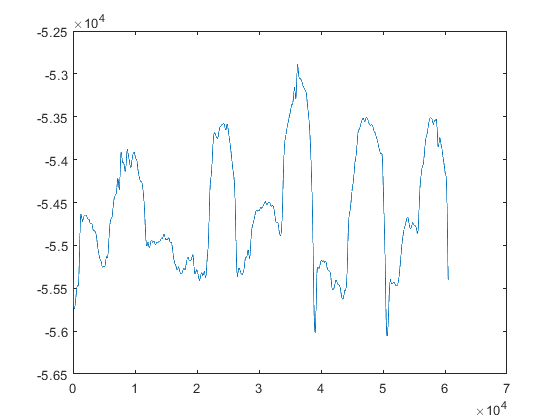

figure
plot(wt(9,:))